# Extended Kalman Filter introduction

The Kalman filter is an algorithm whose objective is to identify the hidden state of a linear dynamic system, said algorithm was developed by Rudolf E. Kalman In 1960. In robotics the hidden state could be the robot pose in given time. This concept is related to localization but  Why we need localizations algorithms ?

In a real scenario the robot makes little mistakes while moves over the field, the sum of mistakes originate that the robot doesn't know where is it with precision.

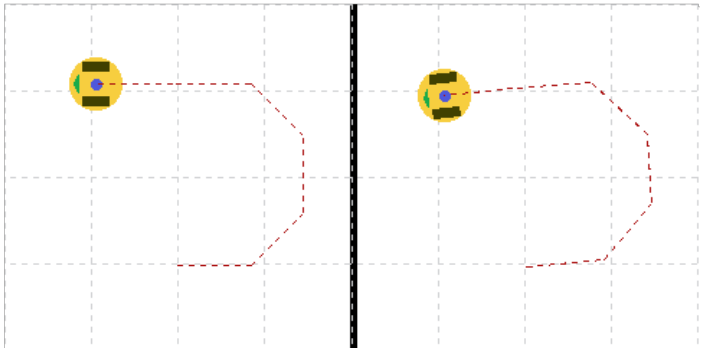

As we saw in previous lesson odometry Isn't enough to know the robot pose, Without a localization system It will be difficult to reach from initial pose to goal pose in a real environment. EKF is a good localization system, however there are others algorithms with different approach such as AMCL.

In this lessos we show the localization problem adding noise to robot movements, and compute odometry as que show in [ NoiseOdometry](matlab:open('../2_Sensors/s_2_NoiseOdometry.mlx')) lesson.

initPose = [ 0.5; 0.5; 1.5707]; % [x ; y ; theta]   
goalPose = [2; 2.5;0];

R = 0.1; 
L = 0.12; 

viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = L; 
mobileRobot = DifferentialDrive(R,L);


Prepare map  to calculate path

                       
[map, mapDilatation]  = generateAugmentedMap(which('world1.png'), 0.1, 10, L); %[path, treshold, scale,robotRadio]
                
[pthObj, solnInfo] = getPathRRT(mapDilatation,initPose,goalPose,0.2,.1,0.2,30000); %[map,initPose,goalPose,MinTurningRadius,ValidationDistance,MaxConnectionDistance,MaxIterations]
              
[controller] = controllerPP(pthObj,0.05,0.1,pi/6); %[pthObj,LookaheadDistance,DesiredLinearVelocity,MaxAngularVelocity)]

Execute simulation.

currentPose = initPose;

varianceV= 0.01; %.3 
varianceW= 0.04; % .1


[sampleTime,tVec,r] = simulTime(0.1,38);
odom_pose = zeros(3,numel(tVec));
odom_pose(:,1) = initPose;

for idx = 2:numel(tVec) 
    

    
    if( sqrt( (odom_pose(1,idx-1)-pthObj.States(end,1))^2 + (odom_pose(2,idx-1)-pthObj.States(end,2))^2 )  < L/2  )
       break
    end
    
    [v,w,lookAheadPt] = controller(odom_pose(:,idx-1));

    [wL,wR] = inverseKinematics(mobileRobot,v ,w);
    

Odometry is computed a we saw in [ Odometry lesson](matlab:open('../2_Sensors/s_1_Odometry.mlx')).

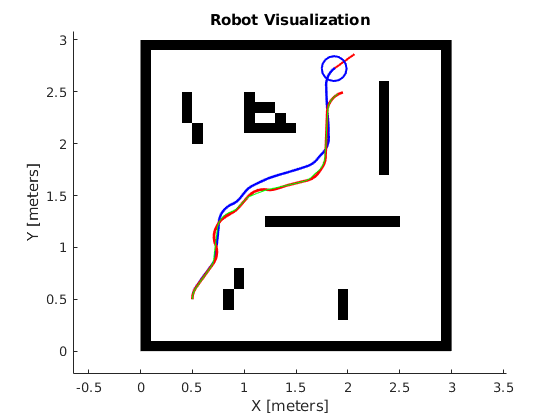

    % Store each pose computed by odometry
    odom_pose(:,idx) =  computeOdometry(R,L,wR,wL,sampleTime ,odom_pose(:,idx-1));
    
  
    v = v  + abs(normrnd(0,varianceV));
    w = w + normrnd(0,varianceW);
    bodyV = [v ;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
    
    % Update visualization
    viz(currentPose);

    %Wait for visualization rate
    waitfor(r);
    
end


hold on

interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)
plot(odom_pose(1,1:idx-1),odom_pose(2,1:idx-1),'g');
hold off

Green line  is the odometry.

Red is path calculatet by RRT*

Blue  is  the robot Trajectory 